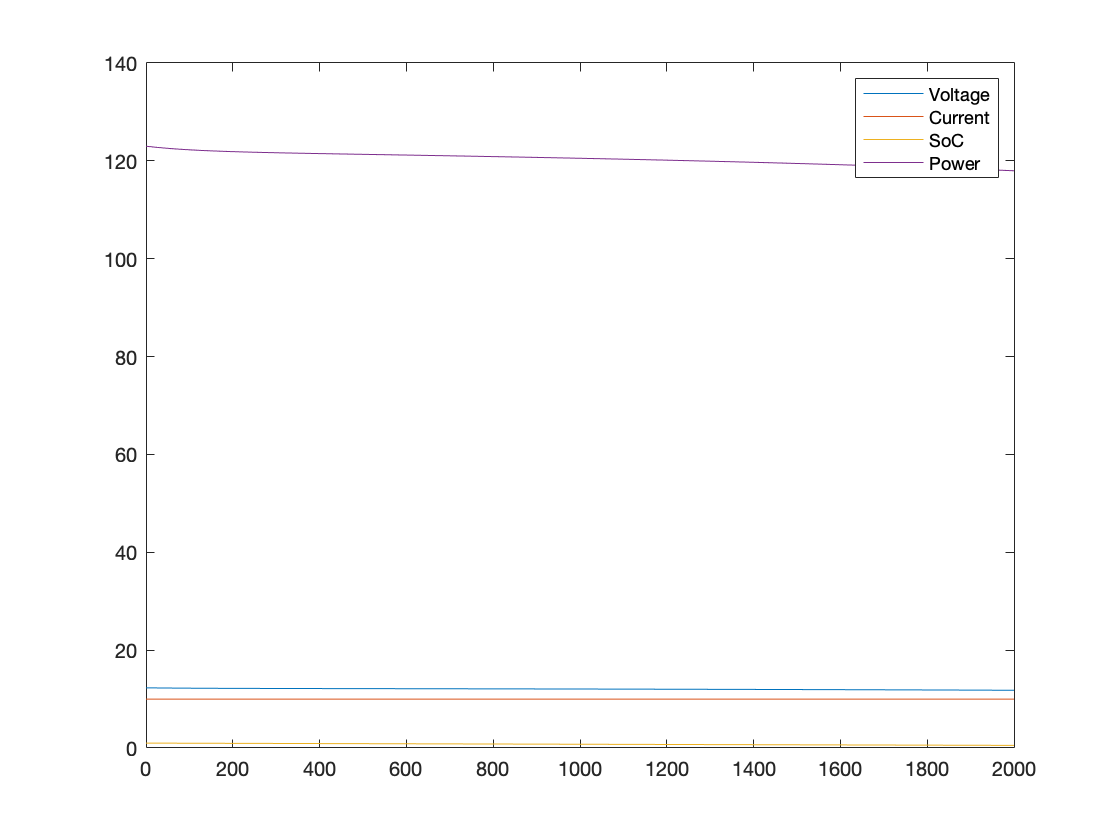

close all; clear;

%Settings values to 0 as a default
LoadSaltVand = 0;
SaltVandON = 0;
SwitchCurrentSaltVand = 0;
CurrentChargeSaltVand = 0;
VoltageChargeSaltVand = 0;
LoadBlySyre = 0;
BlySyreON = 0;
SwitchCurrentBlySyre = 0;
CurrentChargeBlySyre = 0;
VoltageChargeBlySyre = 0;
LoadNiMH = 0;
NiMHON = 0;
SwitchCurrentNiMH = 0;
CurrentChargeNiMH = 0;
VoltageChargeNiMH = 0;
LoadLiStor = 0;
LiIonStorON = 0;
SwitchCurrentLiStor = 0;
CurrentChargeLiStor = 0;
VoltageChargeLiStor = 0;
LoadLille = 0;
LiIonLilleON = 0;
SwitchCurrentLiLille = 0;
CurrentChargeLiLille = 0;
VoltageChargeLiLille = 0;

%Setup values for matlab reading
opstilling = readtable('INSERT STI/matlab.csv');
charge_or_discharge = table2array(opstilling(1,2));
batType = table2array(opstilling(1,1));
load = table2array(opstilling(1,3));
voltage_current = table2array(opstilling(1,4));
sim_length = table2array(opstilling(1,5 ));

%If we have a discharge
if (charge_or_discharge == 0)
    %We choose which battery to use and set the load for that battery
    if(batType == "s")
       SaltVandON = 1;
       LoadSaltVand = load;
    elseif (batType == "b")
        BlySyreON = 1;
        LoadBlySyre = load;
    elseif (batType == "n")
        NiMHON = 1;
        LoadNiMH = load;
    elseif (batType == "lis")
        LiIonStorON = 1;
        LoadLiStor = load;
    elseif (batType == "lil")
        LiIonLilleON = 1;
        LoadLille = load;
    end
   %Runs the simulation
   out = sim('Full_load_sim_doc.slx', sim_length);
end

%If we have to charge. 
if (charge_or_discharge == 1)
    %We set which battery to use and if its current or voltage, and the
    %value for charge cycle
    if(voltage_current == "c")
        if(batType == "s")
           SaltVandON = 1;
           SwitchCurrentSaltVand = 1;
           CurrentChargeSaltVand = load;
        elseif (batType == "b")
           BlySyreON = 1;
           SwitchCurrentBlySyre = 1;
           CurrentChargeBlySyre = load;
        elseif (batType == "n")
           NiMHON = 1;
           SwitchCurrentNiMH = 1;
           CurrentChargeNiMH = load;
        elseif (batType == "lis")
           LiIonStorON = 1;
           SwitchCurrentLiStor = 1;
           CurrentChargeLiStor = load;
        elseif (batType == "lil")
           LiIonLilleON = 1;
           SwitchCurrentLiLille = 1;
           CurrentChargeLiLille = load;
        end
    elseif(voltage_current == "v")
        if(batType == "s")
           SaltVandON = 1;
           SwitchCurrentSaltVand = 0;
           VoltageChargeSaltVand = load;
        elseif (batType == "b")
           BlySyreON = 1;
           SwitchCurrentBlySyre = 0;
           VoltageChargeBLySyre = load;
        elseif (batType == "n")
           NiMHON = 1;
           SwitchCurrentNiMH = 0;
           VoltageChargeNiMH = load;
        elseif (batType == "lis")
           LiIonStorON = 1;
           SwitchCurrentLiStor = 0;
           VoltageChargeLiStor = load;
        elseif (batType == "lil")
           LiIonLilleON = 1;
           SwitchCurrentLiLille = 0;
           VoltageChargeLiLille = load;
        end
    end
   %Runs the simulation
   out = sim('Full_Charge.slx', sim_length);
end

%Output value to ensure we don't send to irrelevant data to the server
if (batType == "s")
    t = out.tout;
    v = out.voltageSaltVand;
    c = out.currentSaltVand;
    s = out.SOCSaltVand;
    p = out.powerSaltVand;
elseif (batType == "b")
    t = out.tout;
    v = out.voltageBlySyre;
    c = out.currentBlySyre;
    s = out.SOCBlySyre;
    p = out.powerBlySyre;
elseif (batType == "n")
    t = out.tout;   
    v = out.voltageNiMH;
    c = out.currentNiMH;
    s = out.SOCNiMH;
    p = out.powerNiMH;
elseif (batType == "lil")
    t = out.tout;
    v = out.voltageLiIonLille;
    c = out.currentLiIonLille;
    s = out.SOCLiIonLille;
    p = out.powerLiIonLille;   
elseif (batType == "lis")
    t = out.tout;   
    v = out.voltageLiIonStor;
    c = out.currentLiIonStor;
    s = out.SOCLiIonStor;
    p = out.powerLiIonStor;
end


%We are making the preparations for a csv file
t = ["time"; t];
v = ["voltage"; v];
c = ["current"; c];
s = ["soc"; s];
p = ["power"; p];

%Adds the matrixes together to make it one big matrix
data = [t, v, c, s, p];

%CSV file creation 
writematrix(data, 'INSERT STI/test_results.csv');


